# INVASIVE MODAL CONTROL (SELF TUNING)

a_model_setup

% Time and sampling
Ts = 1/1000;
num_periods = 20;
T_total = ceil((num_periods*2*pi/model.omega)/Ts)*Ts; % used to ensure at least num_periods are simulated
t_vec = 0:Ts:T_total;
t_num = length(t_vec);

% Initial state: [eta1, eta2, eta_dot1, eta_dot2, I, psi]
x0 = zeros(5,1);

% Store history
t_all = t_vec';
x_all = zeros(t_num, 5);
v_all = zeros(t_num, 1);

% Control gains
model.k1 = 1000;
model.k2 = 0;
model.Ts = Ts;

% Desired trajectory
A_target = 0.01;                 % target amplitude (m)
omega = model.omega;             % target frequency (rad/s)
model.eta_star = @(t) A_target.*sin(omega.*t);
model.eta_ddot_star = @(t) -(A_target*omega^2).*sin(omega.*t);

% iteration outer loop
for n = 1:50
    % simulate itteration:
    for k = 1:length(t_vec)-1
        tk = t_all(k);
        tkp1 = t_all(k+1);
        tspan = [tk, tkp1];
        
        % control force:
        eta_e1 = model.eta_star(tk) - x_all(k, 1);
        control_volt = model.k1*eta_e1;
        v_all(k) = control_volt;
        model.u_fun = @(t) control_volt;
    
        % simulate between samples
        [t_seg, x_seg] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    
        x0 = x_seg(end,:)';
        x_all(k+1, :) = x0;
    end

    % extract amplitude
    tip_disp = x_all(:,1:2) * model.Phiell;
    [t_lin, x_lin] = f_get_last_n_periods(t_all, tip_disp(:,1), 5);
    [A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    amplitude = sqrt(sum(A_vec.^2 + B_vec.^2));
    
    % adjust proporational gain
    amp_rel_error = A_target/amplitude;
    if abs(amp_rel_error - 1) > 0.01
        model.k1 = model.k1*amp_rel_error;
        "Iteration: " + n + " relative amplitude: "+amp_rel_error+"  gain adjusted to: " + model.k1*amp_rel_error
    else
        "Final Tolerance: " + amp_rel_error
        break
    end

end

ans = "Iteration: 1 relative amplitude: 0.52179  gain adjusted to: 272.2629"

ans = "Iteration: 2 relative amplitude: 0.5717  gain adjusted to: 170.5392"

ans = "Iteration: 3 relative amplitude: 4.7373  gain adjusted to: 6694.5874"

ans = "Iteration: 4 relative amplitude: 0.4893  gain adjusted to: 338.3289"

ans = "Iteration: 5 relative amplitude: 0.54638  gain adjusted to: 206.4225"

ans = "Iteration: 6 relative amplitude: 0.59981  gain adjusted to: 135.9211"

ans = "Iteration: 7 relative amplitude: 6.1305  gain adjusted to: 8516.4918"

ans = "Iteration: 8 relative amplitude: 0.49077  gain adjusted to: 334.6037"

ans = "Iteration: 9 relative amplitude: 0.54743  gain adjusted to: 204.3201"

ans = "Iteration: 10 relative amplitude: 0.60731  gain adjusted to: 137.6597"

ans = "Iteration: 11 relative amplitude: 6.1073  gain adjusted to: 8454.5618"

ans = "Iteration: 12 relative amplitude: 0.49108  gain adjusted to: 333.8418"

ans = "Iteration: 13 relative amplitude: 0.54765  gain adjusted to: 203.8902"

ans = "Iteration: 14 relative amplitude: 0.60817  gain adjusted to: 137.7026"

ans = "Iteration: 15 relative amplitude: 6.1739  gain adjusted to: 8630.5571"

ans = "Iteration: 16 relative amplitude: 0.49024  gain adjusted to: 335.9608"

ans = "Iteration: 17 relative amplitude: 0.54705  gain adjusted to: 205.086"

ans = "Iteration: 18 relative amplitude: 0.60599  gain adjusted to: 137.6682"

ans = "Iteration: 19 relative amplitude: 6.1028  gain adjusted to: 8461.2991"

ans = "Iteration: 20 relative amplitude: 0.49095  gain adjusted to: 334.1724"

ans = "Iteration: 21 relative amplitude: 0.54756  gain adjusted to: 204.0767"

ans = "Iteration: 22 relative amplitude: 0.60779  gain adjusted to: 137.6789"

ans = "Iteration: 23 relative amplitude: 6.1734  gain adjusted to: 8633.1724"

ans = "Iteration: 24 relative amplitude: 0.4902  gain adjusted to: 336.0435"

ans = "Iteration: 25 relative amplitude: 0.54703  gain adjusted to: 205.1327"

ans = "Iteration: 26 relative amplitude: 0.60591  gain adjusted to: 137.6715"

ans = "Iteration: 27 relative amplitude: 6.1025  gain adjusted to: 8461.6981"

ans = "Iteration: 28 relative amplitude: 0.49094  gain adjusted to: 334.1935"

ans = "Iteration: 29 relative amplitude: 0.54755  gain adjusted to: 204.0887"

ans = "Iteration: 30 relative amplitude: 0.60776  gain adjusted to: 137.6777"

ans = "Iteration: 31 relative amplitude: 6.1734  gain adjusted to: 8633.3233"

ans = "Iteration: 32 relative amplitude: 0.4902  gain adjusted to: 336.0487"

ans = "Iteration: 33 relative amplitude: 0.54702  gain adjusted to: 205.1356"

ans = "Iteration: 34 relative amplitude: 0.60591  gain adjusted to: 137.6718"

ans = "Iteration: 35 relative amplitude: 6.1025  gain adjusted to: 8461.7234"

ans = "Iteration: 36 relative amplitude: 0.49094  gain adjusted to: 334.1948"

ans = "Iteration: 37 relative amplitude: 0.54755  gain adjusted to: 204.0894"

ans = "Iteration: 38 relative amplitude: 0.60776  gain adjusted to: 137.6776"

ans = "Iteration: 39 relative amplitude: 6.1734  gain adjusted to: 8633.3328"

ans = "Iteration: 40 relative amplitude: 0.4902  gain adjusted to: 336.049"

ans = "Iteration: 41 relative amplitude: 0.54702  gain adjusted to: 205.1358"

ans = "Iteration: 42 relative amplitude: 0.60591  gain adjusted to: 137.6718"

ans = "Iteration: 43 relative amplitude: 6.1025  gain adjusted to: 8461.725"

ans = "Iteration: 44 relative amplitude: 0.49094  gain adjusted to: 334.1949"

ans = "Iteration: 45 relative amplitude: 0.54755  gain adjusted to: 204.0894"

ans = "Iteration: 46 relative amplitude: 0.60776  gain adjusted to: 137.6776"

ans = "Iteration: 47 relative amplitude: 6.1734  gain adjusted to: 8633.3334"

ans = "Iteration: 48 relative amplitude: 0.4902  gain adjusted to: 336.0491"

ans = "Iteration: 49 relative amplitude: 0.54702  gain adjusted to: 205.1358"

ans = "Iteration: 50 relative amplitude: 0.60591  gain adjusted to: 137.6718"

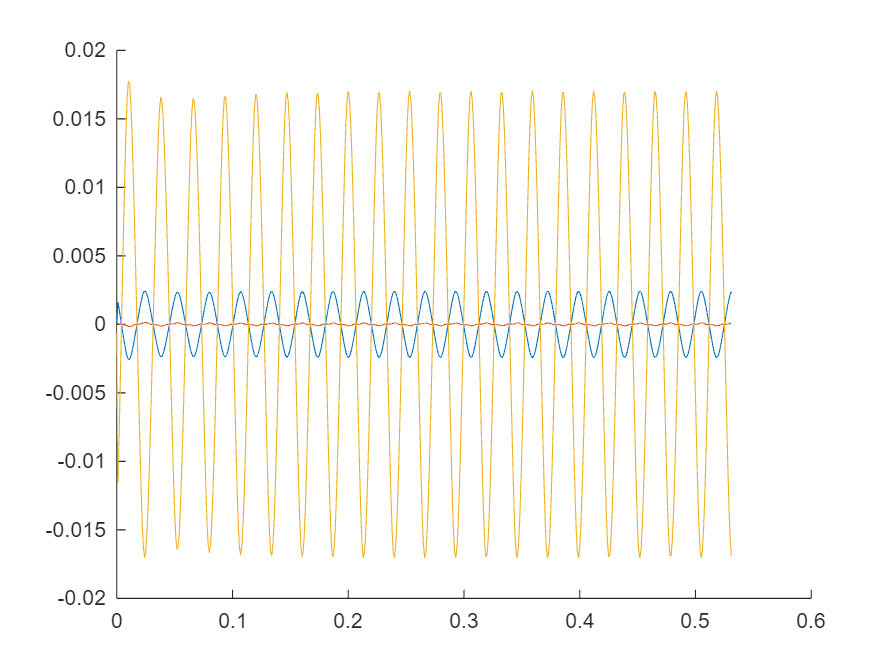

figure;
hold on;

plot(t_all, x_all(:, 1:2))
plot(t_all, tip_disp)

% plot(t_all, v_all./10000)

omega/(2*pi)*0.5

ans = 18.8400